## **Assignment-II**

**Department of Applied Mathematics**

**Noakhali Science and Technology University**

**Course Code: A.MTH 4102, Course Title: Math Practical -V (Using MATLAB)**

*“Coding is the language of the future, and every girl should learn it.”*

 [***Girls Who Code***](https://girlswhocode.com/)***- Reshma Saujani***

**Question-1:**  Write a MATLAB program that reads marks between 0 and 100 and assigns a letter  grade to it according to the following policy: 𝐴 < 95 ,86 < 𝐵 ≤ 95, 76 < 𝐶 ≤ 86 ,66 < 𝐷 ≤ 76 0 < 𝐹 ≤ 66 

**Answer:**

letter_grade(input("Enter marks"))

**Question-2:**  Write a MATLAB program that reads in a set of measurements and calculates the  mean and standard deviation of the input data set, when any value in the data set can be  positive, negative or zero. 

**Answer:**

A = input("Enter Measurement(under [])\n");
fprintf("Measurements Mean is %.2f\nstandard deviation is %.2f", mean(A), std(A))

Measurements Mean is 4.00
standard deviation is 2.37

**Question-3:**  Write a MATLAB program that reads in a set of measurements and calculates the  geometric mean and harmonic mean.

**Answer:**

A = input("Enter Measurement(under [])\n");
fprintf("Measurements Geometric Mean is %.2f\nHarmonic mean is %.2f", geomean(A), harmmean(A))

Measurements Geometric Mean is 0.00
Harmonic mean is 0.00

**Question-4:**  Write a MATLAB program that reads in the integer value for n and calculates its  factorial value, 𝑛!. Also, find 17!

**Answer:**

A = input("Enter a Value");
fprintf("%d factorial is %d\n",A, factorial(A))

15 factorial is 1307674368000


fprintf("17 factorial is %d\n",factorial(17))

17 factorial is 355687428096000


**Question-5:**  Calculate the slope m and intercept b of a least-squares line that best fits an input data  set consisting of an arbitrary number of (x,y) pairs. The input (x,y) data is read from  the key board. Plot both the input data points and the fitted line on a single plot.

**Answer:**

n_points = input('Enter the number of input [x y] points:');
% Read the input data
for ii = 1:n_points
 temp = input('Enter [x y] pair:');
 x(ii) = temp(1);
 y(ii) = temp(2);
end
% Accumulate statistics
sum_x = 0;
sum_y = 0;
sum_x2 = 0;
sum_xy = 0;
for ii = 1:n_points
 sum_x = sum_x + x(ii); 
 sum_y = sum_y + y(ii); 
 sum_x2 = sum_x2 + x(ii)^2; 
 sum_xy = sum_xy + x(ii) * y(ii); 
end
% Now calculate the slope and intercept. 
x_bar = sum_x / n_points;
y_bar = sum_y / n_points;
slope = (sum_xy - sum_x * y_bar) / (sum_x2 - sum_x * x_bar);
y_int = y_bar - slope * x_bar; 
% Tell user.
disp('Regression coefficients for the least-squares line:');

Regression coefficients for the least-squares line:


fprintf(' Slope (m) = %8.3f\n', slope);

 Slope (m) =    1.100


fprintf(' Intercept (b) = %8.3f\n', y_int);

 Intercept (b) =    0.600


fprintf(' No. of points = %8d\n', n_points);

 No. of points =        4


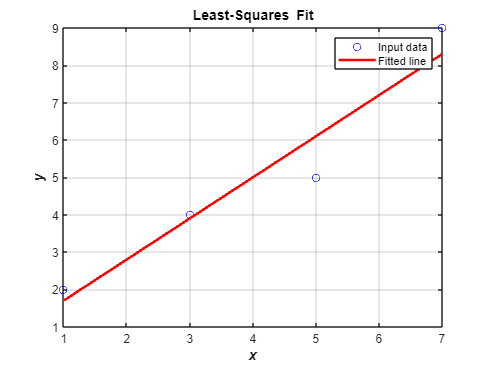

% Plot the data points as blue circles with no 
% connecting lines.
plot(x,y,'bo');
hold on;
% Create the fitted line
xmin = min(x);
xmax = max(x);
ymin = slope * xmin + y_int;
ymax = slope * xmax + y_int;
% Plot a solid red line with no markers
plot([xmin xmax],[ymin ymax],'r-','LineWidth',2);
hold off;
% Add a title and legend
title ('\bfLeast-Squares Fit');
xlabel('\bf\itx');
ylabel('\bf\ity');
legend('Input data','Fitted line');
grid on

**Question-6:**  Write a MATLAB code that will read coordinates of two points and calculate the  distance between them.

**Answer:**

one = input('Enter 1st point in [x y] pair:');
two= input('Enter 2nd point in [x y] pair:');
dist = sqrt((one(1)-two(1))^2 + (one(2)-two(2))^2)

dist = 17.0294

fprintf("Distance is %.2f", dist)

Distance is 17.03

**Question-7:**  Use a MATLAB function that converts a location on a Cartesian plane expressed in  rectangular coordinates into the corresponding polar coordinates with the angle 𝜃 is  expressed in degrees.

**Answer:**

cetrt = input('Cartesian point in [x y] pair:');
[theta,rho] = cart2pol(cetrt(1),cetrt(2));
theta1 = rad2deg(theta);
fprintf("Cartesian is (%.2f , %.2f)\npolar is (%.2f , %.2f)", cetrt(1), cetrt(2), theta1, rho)

Cartesian is (1.00 , 1.00)
polar is (45.00 , 1.41)

**Question-8:**  Use a MATLAB function that converts a location on a Cartesian plane expressed in  polar coordinates with the angle 𝜃 is expressed in degrees into the corresponding  rectangular coordinates.

**Answer:**

pol = input('Cartesian point in [θ r] pair:');
theta1 = deg2rad(pol(1));
[x,y] = pol2cart(theta1,pol(2));

fprintf("polar is (%.2f , %.2f)\ncertesian is (%.2f , %.2f)", pol(1), pol(2), x, y)

polar is (45.00 , 8.00)
certesian is (5.66 , 5.66)

**Question-9:**  Use MATLAB code for sorting data in ascending or descending order and maximum  and minimum value. 

**Answer:**

A = input("Enter data value(under[])\n");
fprintf("sorted in accending [%s]\nsorted in descending[%s]\nMaximum is %d\nminimum is %d",...
    num2str(sort(A)), num2str(sort(A,'descend')), max(A), min(A))

sorted in accending [-4  0  1  2  4  6  8]
sorted in descending[8  6  4  2  1  0 -4]
Maximum is 8
minimum is -4

**Question-10:**  Write a MATLAB code for plotting complex data in the Argand diagram.

**Answer:**

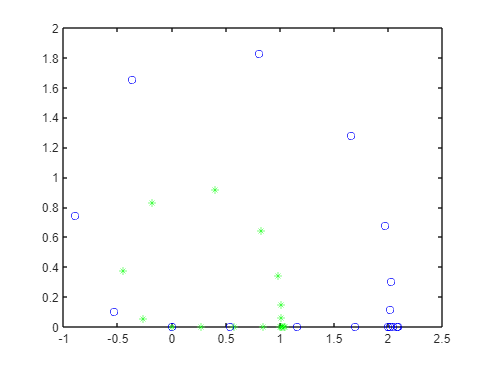

x = -2:0.25:2;
z1 = x.^exp(-x.^2);
z2 = 2*x.^exp(-x.^2);
real_z1 = real(z1);
imag_z1 = imag(z1);

real_z2 = real(z2);
imag_z2 = imag(z2);

plot(real_z1,imag_z1,'g*',real_z2,imag_z2,'bo')

function grade=letter_grade(n)
    if n > 95 
       grade='A';
       fprintf("Grade is %s", grade)
    elseif n > 86 && n < 95
      grade='B';
      fprintf("Grade is %s", grade)
        elseif n > 76 && n < 86
       grade='C';
       fprintf("Grade is %s", grade)
        elseif n > 66 && n < 76
      grade='D';
      fprintf("Grade is %s", grade)
        elseif 0 < n && n < 66 
       grade='F';
       fprintf("Grade is %s", grade)
    end
    end